# Clase 04 >> Sistemas LTI

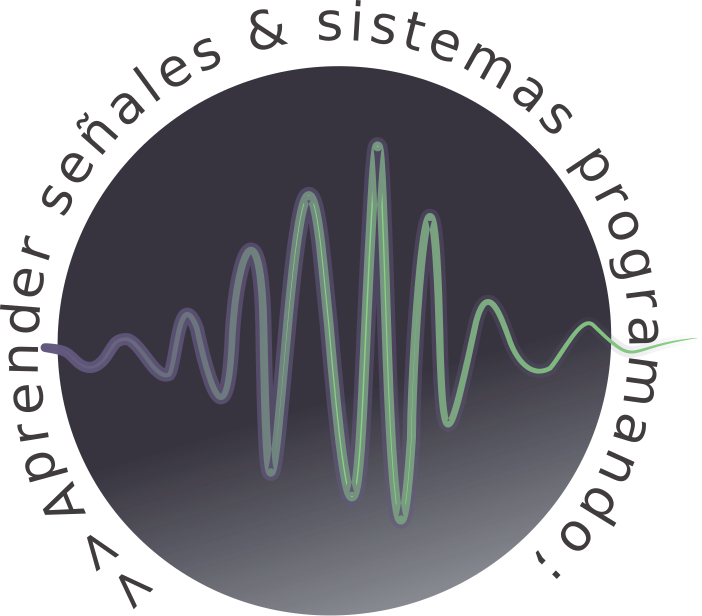

# Convolución continua

La convolución entre dos funciones es un concepto físico importante en muchas ramas de la ciencia. Para el caso de sistemas lineales e invariantes en el tiempo, la **integral de convolución** permite determinar la respuesta del sistema ante cualquier entrada, a partir del conocimiento de la respuesta del sistema ante una única entrada particular: **el impulso **$\delta(t)$. Si la **respuesta impulsiva **se denota como $h(t)$, la salida de un sistema LTI excitado con una entrada cualquiera $x(t)$está dada por la expresión:


$$y(t)=x(t)*h(t)=\int_{-\infty}^{\infty}{x(\tau)h(t-\tau) d\tau}$$


Esta integral se conoce como **integral de convolución o integral de superposicion **y es la representación de una sistema continuo en el tiempo lineal e invariante en función de su respuesta impulsiva $h(t)$.

Aprovechemos para recordar los pasos del procedimiento para realizar la convolución continua:

- **Reflexión**: se refleja h(t) respecto del eje de ordenadas.

- **Desplazamiento: **se desplaza h(-$\tau$) una cantidad t donde se desea evaluar la convolución.

- **Mutiplicación: **Se multiplica la funcion desplazada h(t-$\tau$) y x(t).

- **Integración**: el *área bajo el producto *h(t-$\tau$) y x(t) es el valor de la convolución en el tiempo t.

Consideremos un sistema de **tiempo continuo lineal invariante en el tiempo:**


$$x\left(t\right)=e^{-\mathrm{at}} u\left(t\right),\;a>0$$



$$h\left(t\right)=u\left(t\right)$$



$$y\left(t\right)=x\left(t\right)*h\left(t\right)=\int_{-\infty }^{\infty } x\left(\tau \right)h\left(t-\tau \right)d\tau$$


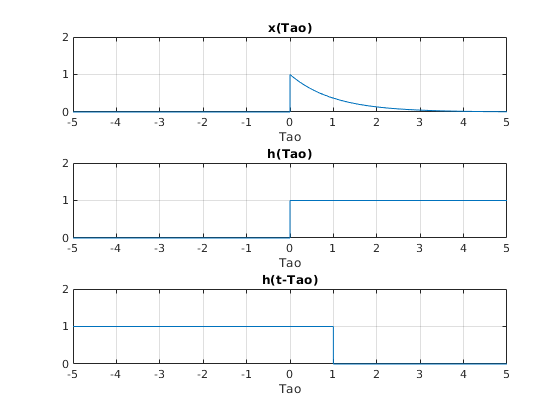

syms  T y t a % T es tau
x = exp(-t)*heaviside(t); % a = 1 (Ej)
h = heaviside(t);
H = heaviside(1-T); % t = 1 (Ej)


clf
subplot(3,1,1)
fplot(x,[-5 5]); xlabel('Tao'); title('x(Tao)'); ylim([0,2]); grid on
subplot(3,1,2)
fplot(h,[-5 5]); xlabel('Tao'); title('h(Tao)'); ylim([0,2]); grid on

subplot(3,1,3)
fplot(H,[-5 5]);xlabel('Tao'); title('h(t-Tao)'); ylim([0,2]); grid on

$$y = -\frac{{\mathrm{e}}^{-a\,t}-1}{a}$$


$$\mathrm{Para}\;t<0,\;y\left(t\right)=0$$



$$\mathrm{Para}\;t\ge 0,\;y\left(t\right)=\int_0^t e^{-a\tau } d\tau$$


y = int(exp(-a*T),'T',0,t)

$$y = 1-{\mathrm{e}}^{-t}$$

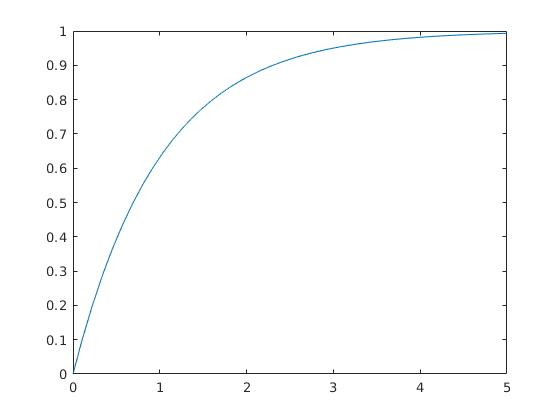

clf

y = subs(y,a,1) 
fplot(y, [0 5])


$$\mathrm{Entonces}\;\mathrm{para}\;t\ge 0,\;y\left(t\right)=\int_0^t e^{-a\tau } d\tau =\frac{1-e^{-\mathrm{at}} }{a}$$



$$y\left(t\right)=\frac{1-e^{-\mathrm{at}} }{a}u\left(t\right),\forall t$$


Ahora consideremos otro sistema de **tiempo continuo lineal invariante en el tiempo:**


$$x(t)=\begin{cases} 1\text{ , para } 0\leq t<T \\ 
0\text{ , para el resto}
\end{cases}$$



$$h(t)=\begin{cases} t\text{ , para } 0\leq t<T \\ 
0\text{ , para el resto}
\end{cases}$$


Un caso particular puede ser:


$$x(t)=\begin{cases} 1\text{ , para } 0\leq t<5 \\ 
0\text{ , para el resto}
\end{cases}$$



$$h(t)=\begin{cases} t\text{ , para } 0\leq t<10 \\ 
0\text{ , para el resto}
\end{cases}$$


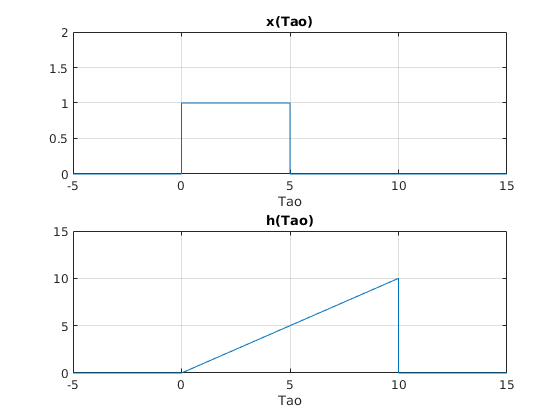

syms  T y t a % T es tau
x = heaviside(t)-heaviside(t-5); 
h = t*heaviside(t)-t*heaviside(t-10);  

clf
subplot(2,1,1)
fplot(x,[-5 15]); xlabel('Tao'); title('x(Tao)'); ylim([0,2]); grid on

subplot(2,1,2)
fplot(h,[-5 15]); xlabel('Tao'); title('h(Tao)'); ylim([0,15]); grid on

$$y = \frac{t^{2}}{2}$$


$$\textrm{Para}\;t<0,\;y\left(t\right)=0$$



$$\left\lbrace \begin{array}{cc}
t & >0\\
t-5 & \le 0
\end{array}\right.\;\Rightarrow 0<t\le 5,y\left(t\right)=\int_0^t \tau \;d\tau =\frac{\mathrm{t²}}{2}$$


y = int(T,'T',0,t)

$$y = 5\,t-\frac{25}{2}$$


$$\left\lbrace \begin{array}{cc}
t-5 & >0\\
t & \le 10
\end{array}\;\Rightarrow 5<t\le 10,y\left(t\right)=\int_{t-5}^t \tau \;d\tau =5t-\frac{25}{2}\right.$$


y = int(T,'T',t-5,t)

$$y = 50-\frac{{\left(t-5\right)}^{2}}{2}$$


$$\left\lbrace \begin{array}{cc}
t & >10\\
t-5 & \le 10
\end{array}\;\Rightarrow 10<t\le 15,y\left(t\right)=\int_{t-5}^{10} \tau \;d\tau =50-\frac{\left(t-5\right)\textrm{²}}{2}\right.$$


y = int(T,'T',t-5,10)


$$t-5>10\Rightarrow t>15,y\left(t\right)=0$$



$$y\left(t\right)=\frac{\textrm{t²}}{2}u\left(t\right)-\frac{\textrm{t²}}{2}u\left(t-5\right)+5t-\frac{25}{2}u\left(t-10\right)+50-\frac{\left(t-5\right)\textrm{²}}{2}$$

$$u\left(t-15\right)$$


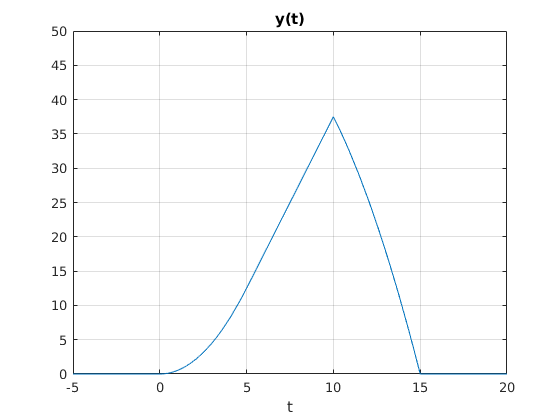

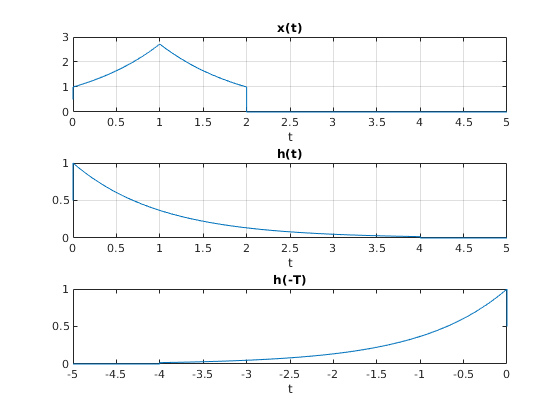

$$ans = \frac{{\mathrm{e}}^{2\,t}}{2}-\frac{1}{2}$$

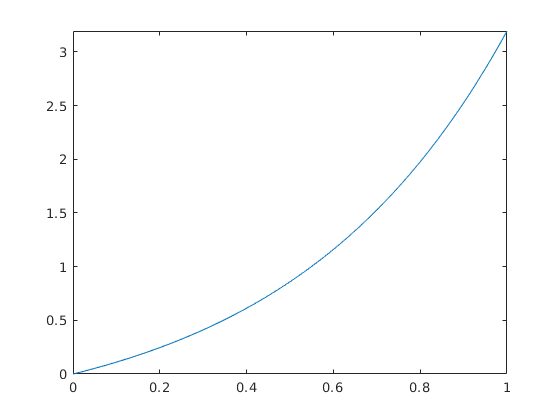

y = (t^2)/2*heaviside(t)-(t^2)/2*heaviside(t-5)+((5*t)-(25/2))*heaviside(t-5)-((5*t)-(25/2))*heaviside(t-10)+(50-((t-5)^2)/2)*heaviside(t-10)-(50-((t-5)^2)/2)*heaviside(t-15); 


clf
fplot(y,[-5 20]); xlabel('t'); title('y(t)'); ylim([0,50]); grid on

# Convolución discreta

Un sistema representado en entrada/salida por lo general se expresa en términos de su respuesta al pulso unitario, la cual se define como $h[n]$. Esta respuesta es el resultado de aplicar un pulso unitario $\delta [n]$ en la entrada, es decir $x[n] = \delta [n]$. Por las propiedades de causalidad la respuesta al pulso unitario $h[n]$ debe ser cero para todos los enteros n < 0.


$$y[n] = \sum_{i=0}^{n}{h[i]x[n-i]} , n\ge 0,$$


se lo conoce como la convolución de $h[n]$ y $x[n]$, y se denota com el símbolo "$*$", por lo tanto:


$$y[n] = h[n]*x[n]=\sum_{i=0}^{n}{h[i]x[n-i]}.$$


Una consecuencia interesante de la representación de convolución es que el sistema está determinado completamente por la respuesta al pulso unitario $h[n]$. En particular, si conocemos $h[n]$, la respuesta de salida resultante de cualquier entrada $x[n]$ puede calcularse, evaluando la ultima ecuación.

Veamos un ejemplo de la convolución de un pulso unitario consigo mismo [Kamen, Edward W., 2008]:

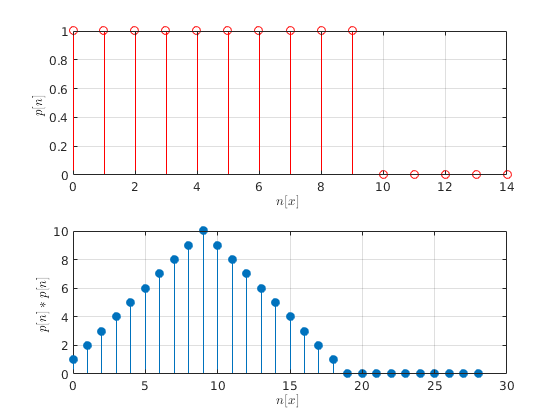

p = [ones(1,10) zeros(1,5)]; % corresponde de n = 0 a n = 14
x = p; h = p;
y = conv(x,h);
n = 0:28; 
subplot(2,1,1)
N = 0:14;
stem(N,x,'r'); xlabel('$$ n[x] $$ ','interpreter','latex'); ylabel('$$ p[n] $$ ','interpreter','latex');
grid on
subplot(2,1,2)

stem(n,y,'filled'); xlabel('$$ n[x] $$ ','interpreter','latex'); ylabel('$$ p[n]*p[n] $$ ','interpreter','latex');
grid on  

La convolución tambien la podemos ver como la multiplicación de polinomios, como en el siguiente ejemplo:


$$(x^2+1)(2x+7) = 2x^3+7x^2+2x+7$$


u = [1 0 1];

w =      2     7     2     7


v = [2 7];
w = conv(u,v)

Esta multiplicación no es posible realizarla de la siguiente forma

% w = u*v; 
% w = u.*v;

ans = logical
   1


En ambos casos la loguitud del vector resultante es 

(length(u) + length(v) - 1 ) & length(w)

## Cálculo de la salida del sistema (Script_04_01)

Ahora vamos a considerar un sistema de tiempo discreto (señal digital) lineal e invariante en el tiempo y causal, por ejemplo la respuesta acustica de un recinto frente a un estimulo sonoro con:

- Señal de entrada $x[n]$.

- Respuesta al impulso del recinto $h[n]$.

- La respuesta del recinto frente al estimulo $x[n]$es igual a la convolución de tiempo discreto $h[n]*x[n]$.

Descargue del siguiente link [http://www.openairlib.net/](#null) , una respuesta al impulso y una señal anecoica. A partir de estos dos archivos diseñe un script que convoluciones dichas señales y obtener la señal como si se ejecutara en dicho recinto. Como se demostrará en futuras unidades la convolucion es costoso computacionalmente hablando, para realizar dicho procedimiento se utilizara propiedades de la Transformada de Fourier, de modo de aumentar el rendimiento en los calculos.

% script_04_01()

## Ejercicios de la guía n°3 (script_04_02)

Resolver el ejercicio n°1 con un script en MATLAB.

Ejemplo, verifique las siguientes igualdades:


$$\text{a. } x(t)*\delta(t) = x(t)$$



$$\text{b. } x(t)*\delta(t-t_0) = x(t-t_0)$$


% script_04_02()

## Ejercicios de la guía n°3 (script_04_03)

Resolver el ejercicio n°2 con un script en MATLAB.

Ejemplo,la entrada y la respuesta al impulso de un sistema continuo, lineal e invariante en el tiempo (LTI), están dadas por las siguientes expresiones:


$$x(t) = u(t)\text{;     } h(t) = e^{-\alpha t}u(t) \text{,   } \alpha >0$$


Obtenga la salida y(t), emple

## Referencias

- Kamen, Edward W., and Bonnie S. Heck. ***Fundamentos de señales y sistemas usando la Web y Matlab***. Pearson Prentice-Hall, 2008.